# **ECE 1473 OFDM Tutorial: **

# **Modulate Single Symbol of OFDM from Bits**

## **Author: Adam Nichols**

## Introduction:

Welcome to an introduction to OFDM digital modulation!

This set of MATLAB live scripts will be a tutorial on how to use communications concepts and modules to modulate OFDM.

## Background:

    As per Couch in Digital and Analog Communications Systems: "Orthogonal Frequency Division Multiplexing (OFDM) is a technique for transmitting data in parallel by using a large number of modulated carriers with sufficient frequency spacing so that the carriers are orthogonal" [1]. The block diagram illustrating the modules of an OFDM modulator can be seen below in figure 1. 

    This means that OFDM sends many bits in parallel at the same time. For example, an OFDM signal could look like 1000 parallel individual bitstreams all packed together into one giant signal. These bits will be used as Fourier Series Coefficients and used in the IFFT algorithm to generate a digitally sampled analog signal. This analog symbol represents the baseband message that will be later sent over the air (OTA).

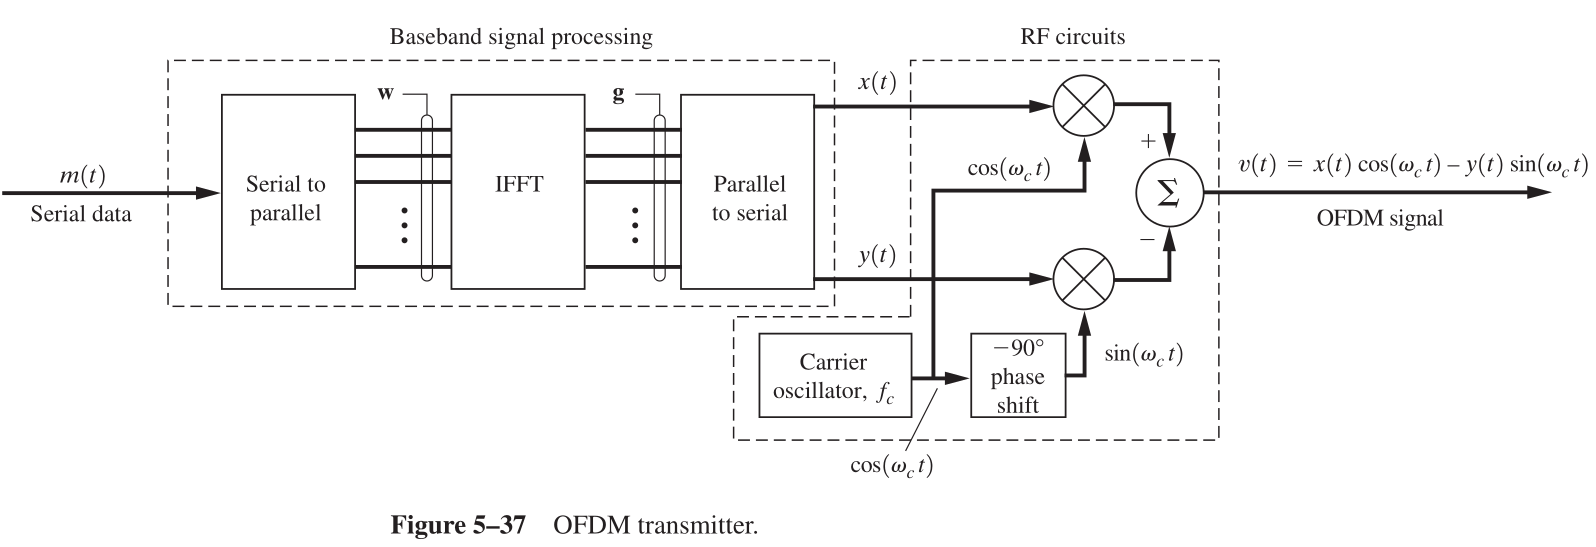

FIgure 1: Block diagram of OFDM transmitter from Couch [1]

    The parallelization used in OFDM has certain advantages in wireless communications, such as reducing the impact of multipath interference and narrowband jamming [1]. Further, any notch or narrowband interference may knock out only several bits of the entire 1000 bit symbol, but a single carrier modulation scheme would be completely disrupted. 

    OFDM is used in the physical layer of modern, high throughput and reliable communications systems and IOT devices [2]. Further, IEEE 802.11ax (a.k.a WiFi 6) uses an offshoot of OFDM called OFDMA (Orthogonal Frequency Division Multiple Access) to enable multiple users to access the same frequency channel [3]. OFDM is a very relevant topic in the modern wireless scene. 

## OFDM Single Symbol Modulation:

    The following MATLAB script will provide a method to modulate a simple, single symbol of OFDM. First, some data must be generated to be modulated with OFDM. For the purpose of this section, a set of random bits will be used. 

### Random Data Generation:

    First, choose a number of bits to send in a single symbol of OFDM. A default value of 32 is chosen to help illustrate different properties of OFDM later in this script.

num_bits = 32;

    All of these bits will be sent in one symbol of OFDM, so the number of bits will dictate the number of carriers used in this symbol. This variable to represent the number of carriers will be the same as the number of bits in this example, but could be different for higher order signal constellations. For now, the binary case will be considered (this means each carrier will be BPSK - Binary Phase Shift Keying). This variable is used to provide clarity when referring to the signal in frequency domain contexts.

num_carriers = num_bits;

    The following segment generates the random data using the rand function. Rand generates a vector of values uniformly distributed between 0 and 1. A vector of bits is generated by rounding (to nearest) each of these values to 0 or 1.

bits = round(rand(num_bits,1));

    The following generates the stem plot to shown to the right to visualize the bits that will be sent. Before modulation, bits will take the value of 0 or 1.

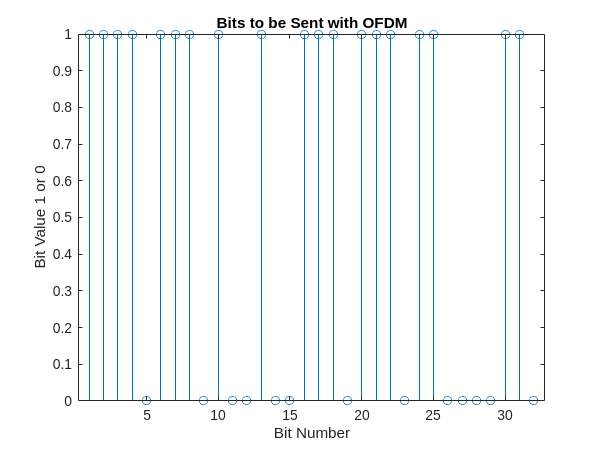

figure(1)
clf
stem(1:num_bits, bits)
title("Bits to be Sent with OFDM")
xlabel("Bit Number")
ylabel("Bit Value 1 or 0")

    Next, these bits will be converted into Fourier Series Coefficients. Polar NRZ (non-return to zero) antipodal signalling will be used. This is a line code characterized by "Binary 1's and 0's are represented by equal positive and negative levels" and the pulse holds its value for its entire duration [1]. The data bits will be converted into antipodal bits so that 1's will take a value of 1 and 0's will take a value of -1. 

tx_bits = bits*2 - 1;

    These antipodal bits are shown in a stem plot on the sidebar. These represent Fourier coefficients for a DFT of the time domain signal.

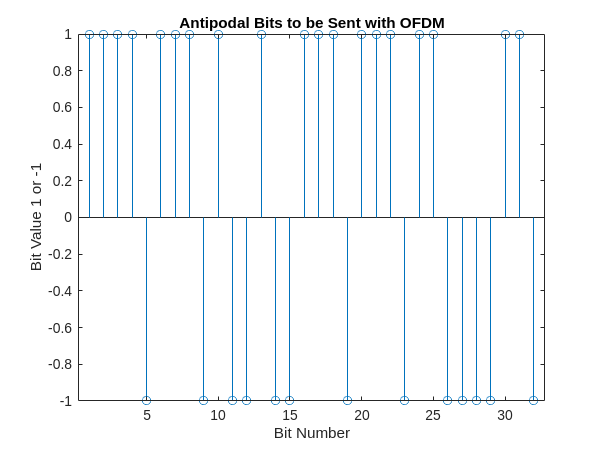

figure(2)
clf
stem(1:num_bits, tx_bits)
title("Antipodal Bits to be Sent with OFDM")
xlabel("Bit Number")
ylabel("Bit Value 1 or -1")

### IFFT Modulation:

    Next, the IFFT is performed on the antipodal bits to get the time domain signal. Since the data is random and without any particular symmetry, the signal will contain both real and imaginary components.

s_t = ifft(tx_bits);

    Next, several parameters of the OFDM modulation will be defined based on the bitrate and number of carriers chosen. The OFDM symbol rate and symbol time describe how often entire OFDM symbols are sent. The OFDM sample period and sample rate describe the timing information of the IFFT result. A time vector t is generated to plot against the time domain message.

    Use the drop down menu to select a bitrate.

bitrate = 1e4;
OFDM_symbolrate = bitrate / num_carriers;
OFDM_symboltime = 1/OFDM_symbolrate;
OFDM_sampleperiod = OFDM_symboltime / num_carriers;
OFDM_samplerate = 1/OFDM_sampleperiod;
t = (0:num_bits-1)*OFDM_sampleperiod;

    The output of the IFFT is plotted against time. This plot represents the time domain signals (real and imaginary components) in the baseband message that represent the bits in an analog channel. The waveform is quite jagged because this is the minimum samples required to represent the data. Upsampling to see a better representation will be seen later.

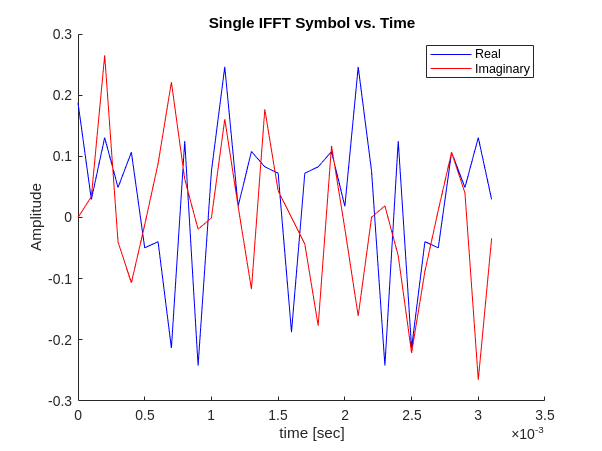

figure(3)
clf
hold on
plot(t, real(s_t), 'b-')
plot(t, imag(s_t), 'r-')
hold off
title("Single IFFT Symbol vs. Time")
xlabel("time [sec]")
ylabel("Amplitude")
legend("Real","Imaginary")

    To verify the output of the IFFT accurately represents the bits, the magnitude spectrum is generated and plotted. The spectrum has a flat response, which is exactly what is expected. All the Fourier coefficients take a value of 1 or -1, so when the absolute value is taken just all 1's remain. This yields the expected flat response.

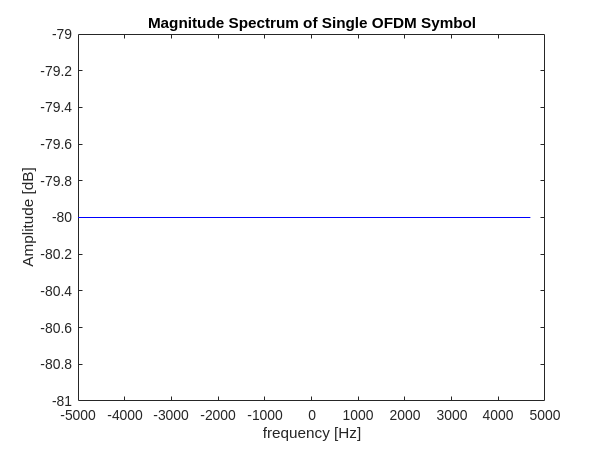

[f, spec] = GetSpectrum(t, s_t, OFDM_samplerate);
mag_spec = 20*log10(abs(spec));
figure(4)
clf
plot(f, mag_spec, 'b-')
title("Magnitude Spectrum of Single OFDM Symbol")
xlabel("frequency [Hz]")
ylabel("Amplitude [dB]")

### Upsampling the Baseband Message:

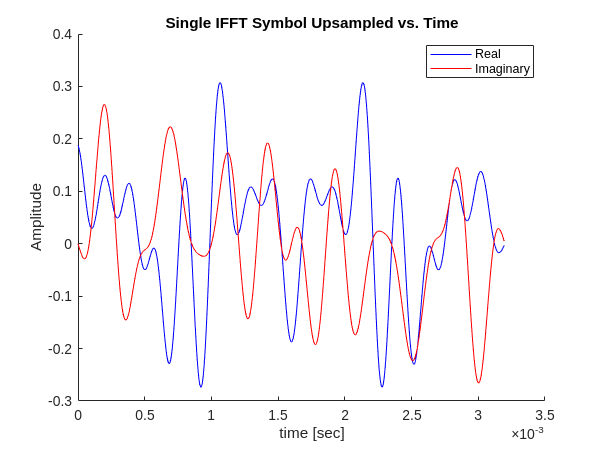

%% upsample the baseband message to see out of band distortion due to windowing
upsamp = 16;
OFDM_samplerate_resamp = OFDM_samplerate*upsamp;
OFDM_sampleperiod_resamp = OFDM_sampleperiod/upsamp;
s_t_resamp = resample(s_t,upsamp,1);
t_resamp = transpose((0:upsamp*num_bits-1)*OFDM_sampleperiod_resamp);


% plot the upsampled time domain message
figure(5)
clf
hold on
plot(t_resamp, real(s_t_resamp), 'b-')
plot(t_resamp, imag(s_t_resamp), 'r-')
hold off
title("Single IFFT Symbol Upsampled vs. Time")
xlabel("time [sec]")
ylabel("Amplitude")
legend("Real","Imaginary")

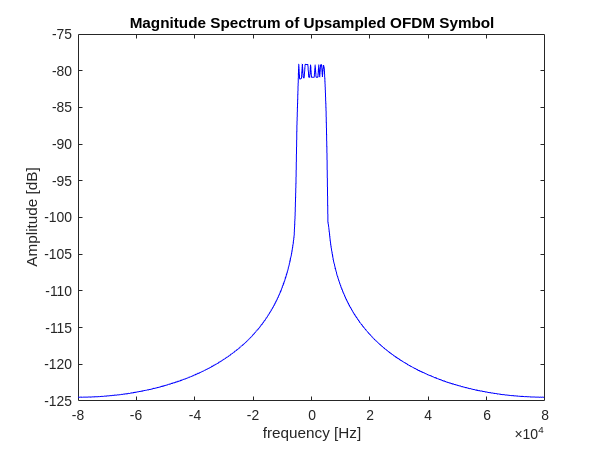


% plot the spectrum of the upsampled message
[f_resamp, spec_resamp] = GetSpectrum(t_resamp, s_t_resamp, OFDM_samplerate_resamp);
mag_spec_resamp = 20*log10(abs(spec_resamp));
figure(6)
clf
plot(f_resamp, mag_spec_resamp, 'b-')
title("Magnitude Spectrum of Upsampled OFDM Symbol")
xlabel("frequency [Hz]")
ylabel("Amplitude [dB]")

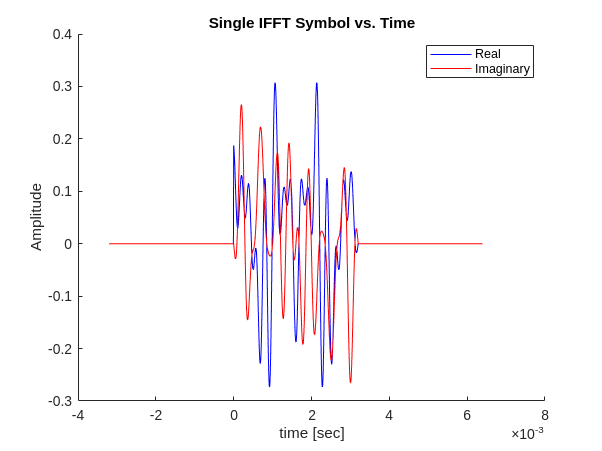


%% zero pad the upsampled message to show transition time distortion

% pad the time domain message with extra zeros (silent guard interval)
t_padded = transpose((-num_bits*upsamp:2*num_bits*upsamp-1)*OFDM_sampleperiod_resamp);
s_t_padded = zeros(3*num_bits*upsamp, 1, 'like', 1j);
s_t_padded(num_bits*upsamp+1:2*num_bits*upsamp) = s_t_resamp;

% plot the padded time domain message
figure(7)
clf
hold on
plot(t_padded, real(s_t_padded), 'b-')
plot(t_padded, imag(s_t_padded), 'r-')
hold off
title("Single IFFT Symbol vs. Time")
xlabel("time [sec]")
ylabel("Amplitude")
legend("Real","Imaginary")

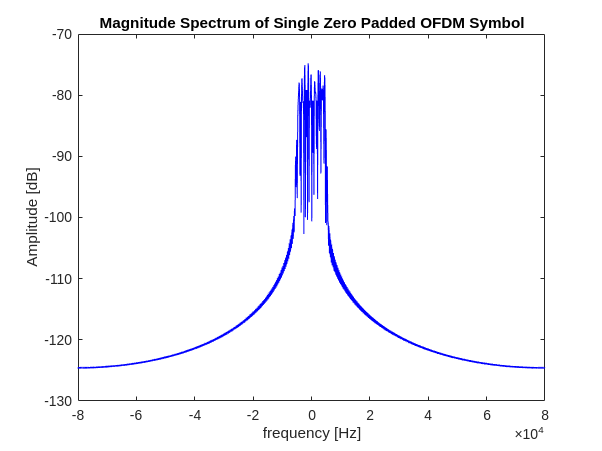


% find the spectrum of the original and padded message

[f_padded, spec_padded] = GetSpectrum(t_padded, s_t_padded, OFDM_samplerate_resamp);
mag_spec_padded = 20*log10(abs(spec_padded));

% plot the magnitude spectrum of the padded message
figure(8)
clf
plot(f_padded, mag_spec_padded, 'b-')
title("Magnitude Spectrum of Single Zero Padded OFDM Symbol")
xlabel("frequency [Hz]")
ylabel("Amplitude [dB]")

## References:

[1] L. W. Couch, *Digital and Analog Communication Systems*. Upper Saddle River, N.J: Pearson, 2013. 

[2] “Wi-Fi: Overview of the 802.11 physical layer and transmitter measurements,” Tektronix, https://www.tek.com/en/documents/primer/wi-fi-overview-80211-physical-layer-and-transmitter-measurements (accessed Feb. 16, 2025). 

[3] R. Awati and L. Fitzgibbons, “What is OFDMA (orthogonal frequency-division multiple access)?: Definition from TechTarget,” Search Networking, https://www.techtarget.com/searchnetworking/definition/orthogonal-frequency-division-multiple-access-OFDMA (accessed Feb. 16, 2025). 